## First, simple problem

scalar problem, non generalized

clear; clc; close all
syms x_f y_f z_f F_x F_y F_z x_c y_c z_c x_f0 y_f0 z_f0 x_c0 y_c0 z_c0 mg theta 'real'

mass = 1;

eq1 = F_x == mg * ((x_c0+z_c0*tan(theta)) / (x_f0*tan(theta)-z_f0))

eq_sub = subs(eq1, [x_c0, z_c0, x_f0, z_f0], [-0.4, 1, -0.8, 1.5])

$$eq1 = F_{x}=-\frac{\mathrm{mg}\,\left(x_{\mathrm{c0}}+z_{\mathrm{c0}}\,\tan\left(\theta \right)\right)}{z_{\mathrm{f0}}-x_{\mathrm{f0}}\,\tan\left(\theta \right)}$$

eq_eval = eval(eq_sub)
fxs = [];

$$eq\_sub = F_{x}=-\frac{\mathrm{mg}\,\left(\tan\left(\theta \right)-\frac{2}{5}\right)}{\frac{4\,\tan\left(\theta \right)}{5}+\frac{3}{2}}$$

angles = [];

$$eq\_eval = F_{x}=-\frac{\mathrm{mg}\,\left(\tan\left(\theta \right)-\frac{2}{5}\right)}{\frac{4\,\tan\left(\theta \right)}{5}+\frac{3}{2}}$$


for angle = linspace(0,deg2rad(21),100)
    eq_w_angle = subs(eq_sub, [theta, mg], [angle, mass*9.8]);
    rhs_of_eq = rhs(eq_w_angle);
    fxs = [fxs; double(rhs_of_eq)];
    angles = [angles; angle];
end

plot(fxs, angles);
hold on;

fxs=[];
angles=[];

% What about other values of mass?
mass = 5; % kg
for angle = linspace(0,deg2rad(21),100)
    eq_w_angle = subs(eq_sub, [theta, mg], [angle, mass*9.8]);
    rhs_of_eq = rhs(eq_w_angle);
    fxs = [fxs; double(rhs_of_eq)];
    angles = [angles; angle];
end

plot(fxs, angles)


## Let's generalize this Jawn!

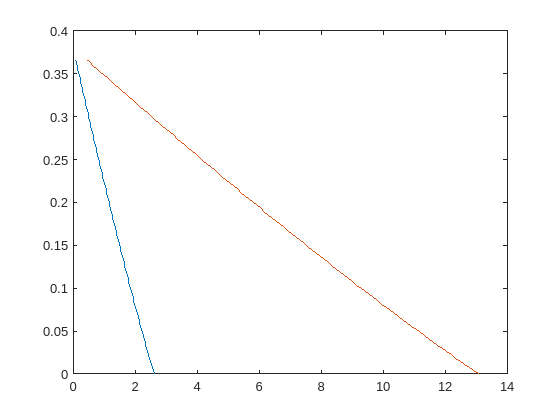

$$LHS = F_{x}\,\left({\hat{e}}_{y}\,r_{f,z}-{\hat{e}}_{z}\,r_{f,y}\right)-F_{y}\,\left({\hat{e}}_{x}\,r_{f,z}-{\hat{e}}_{z}\,r_{f,x}\right)+F_{z}\,\left({\hat{e}}_{x}\,r_{f,y}-{\hat{e}}_{y}\,r_{f,x}\right)$$

$$RHS = {\hat{e}}_{x}\,\mathrm{mg}\,r_{c,y}-{\hat{e}}_{y}\,\mathrm{mg}\,r_{c,x}$$

$$eq = F_{x}\,\left({\hat{e}}_{y}\,r_{f,z}-{\hat{e}}_{z}\,r_{f,y}\right)-F_{y}\,\left({\hat{e}}_{x}\,r_{f,z}-{\hat{e}}_{z}\,r_{f,x}\right)+F_{z}\,\left({\hat{e}}_{x}\,r_{f,y}-{\hat{e}}_{y}\,r_{f,x}\right)={\hat{e}}_{x}\,\mathrm{mg}\,r_{c,y}-{\hat{e}}_{y}\,\mathrm{mg}\,r_{c,x}$$

$$sol\_mg = \frac{3\,F_{x}}{2}+\frac{4\,F_{z}}{5}=\frac{98}{25}$$

sol = struct with fields:
    F_x: 196/75
    F_y: 0
    F_z: 0


F_solved =     2.6133
         0
         0


clear


mass = 0.5; % This just changes the scale of the slope --> mass estimation??
evaluate_F = get_evaluator_fn(mass);

% Saved angles from simulated (experimental) data
load('simulated_angles.mat'); % loaded into 'angles' var
angles = angles(angles<deg2rad(60));

ndata = length(angles);

% Calculate force response based on physics formulation
force_out = zeros(ndata,3);
for i = 1:ndata
    force_out(i,:) = reshape(evaluate_F(angles(i)), [1,3]);
end

% Calculate force norm
force_norm = zeros(ndata,1);
for i=1:ndata
    force_norm(i,:) = norm(force_out(i,:));
end

fig = figure();
plot(rad2deg(angles), force_out(:,1), 'r', LineWidth=3); hold on;
plot(rad2deg(angles), force_out(:,2), 'g'); hold on;
% plot(rad2deg(angles), force_out(:,3), 'b'); hold on;
% plot(rad2deg(angles), force_norm,     'k'); hold off;

xlim([-1, 30])
ylim([-0.01, inf])%0.5])

xlabel('Payload Angle (deg) for Tipping Axis $\hat{e}=\hat{y}$', 'Interpreter','latex')
ylabel('Recorded x-force (N)')
legend('x-force')%, 'y-force', 'z-force');


## Real quick, let's try flipping the basic case to isolate theta

(non general case)

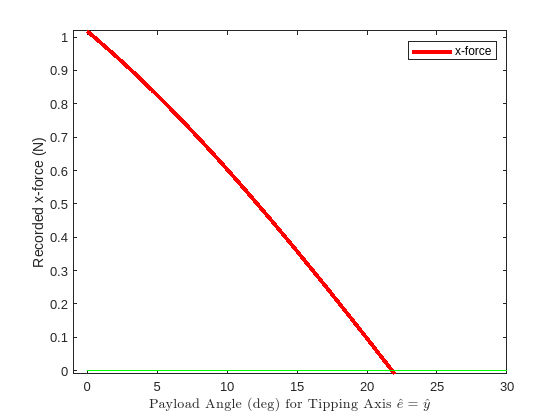

clear

syms F_x F_z


rf0 = [-0.08; 0; 0.15]; % Finger pos in box frame at t=0
rc0 = [-0.04; 0; 0.1];  % CoM pos in box frame at t=0
m = 0.5;   % kg
g = 9.81;   % gravity

% theta_eq = atan2(F_z*rf0(3) + F_x*rf0(1) - m*g*rc0(3) , m*g*rc0(1) - F_z*rf0(1) + F_x*rf0(3))
% theta_eq = atan2((m*g*rc0(1) - F_z*rf0(1) + F_x*rf0(3)) , (F_z*rf0(3) + F_x*rf0(1) - m*g*rc0(3)));
theta_eq = atan((m*g*rc0(1) - F_z*rf0(1) + F_x*rf0(3)) / (F_z*rf0(3) + F_x*rf0(1) - m*g*rc0(3)));

for f = linspace(0.8, 1e-3, 30)
    theta_sol = eval(subs(theta_eq, [F_x, F_z], [f, 0]));
    f;
    rad2deg(theta_sol);
end

% And of course, let's test when Force is zero:
rad2deg(eval(subs(theta_eq, [F_x, F_z], [0,0])))


## AT LONG LAST

Let's use the generalized form, isolating theta

% --- Drop-in Code to Calculate Tipping Angle vs. Applied Force ---

clear; clc; close all;

f = 0.8000

ans = 7.8246

f = 0.7724

ans = 8.2758

f = 0.7449

ans = 8.7295

f = 0.7173

ans = 9.1857

f = 0.6898

ans = 9.6445

f = 0.6622

ans = 10.1057

f = 0.6347

ans = 10.5693

f = 0.6071

ans = 11.0353

f = 0.5796

ans = 11.5036

f = 0.5520

ans = 11.9742

f = 0.5245

ans = 12.4471

f = 0.4969

ans = 12.9222

f = 0.4694

ans = 13.3994

f = 0.4418

ans = 13.8787

f = 0.4143

ans = 14.3600

f = 0.3867

ans = 14.8433

f = 0.3592

ans = 15.3285

f = 0.3316

ans = 15.8156

f = 0.3041

ans = 16.3045

f = 0.2765

ans = 16.7952

f = 0.2490

ans = 17.2875

f = 0.2214

ans = 17.7815

f = 0.1939

ans = 18.2770

f = 0.1663

ans = 18.7739

f = 0.1388

ans = 19.2723

f = 0.1112

ans = 19.7721

f = 0.0837

ans = 20.2731

f = 0.0561

ans = 20.7753

f = 0.0286

ans = 21.2787

f = 1.0000e-03

ans = 21.7831


m = 0.5;         % Mass (kg)
g = 9.81;        % Gravity (m/s^2)

ans = 21.8014


rf0 = [-0.08; 0; 0.15];  % Moment arm for applied force F
rc0 = [-0.04; 0; 0.1];   % Moment arm for center of mass

e_hat = [0; 1; 0];       % Tipping edge axis
z_hat = [0; 0; 1];       % Vertical axis (for gravity)

% We will vary the Fx component of the force F.
num_points = 200; % Number of force values to test
Fx_values = linspace(0.8, 1e-3, num_points); % Array of Fx values [N]

% Pre-allocate arrays to store results for efficiency
theta_values = zeros(1, num_points); % Will store theta in radians
F_vectors = zeros(3, num_points);    % Will store the full F vector

% Loop through each value of Fx
for i = 1:length(Fx_values)
    F = [Fx_values(i); 0; 0];
    F_vectors(:, i) = F; % Define & Store the full vector

    % --- Numerator of the arctan argument ---
    num_term_W = m * g * dot(e_hat, cross(rc0, z_hat));
    num_term_F = dot(e_hat, cross(rf0, F));
    numerator = num_term_W - num_term_F;

    % --- Denominator of the arctan argument ---
    den_term_F = (dot(F, e_hat) * dot(e_hat, rf0)) - dot(F, rf0);
    den_term_W = m * g * ((dot(z_hat, e_hat) * dot(e_hat, rc0)) - dot(z_hat, rc0));
    denominator = den_term_F - den_term_W;
    
    % --- Calculate theta using atan2 for quadrant-correct results ---
    % theta = atan2(Y, X) is more robust than atan(Y/X)
    theta_values(i) = atan2(numerator, denominator);
end

%% 4. Display and Plot Results (Optional)
% The script saves results to 'Fx_values' and 'theta_values' as requested.
% This section provides immediate visualization.

% Convert theta to degrees for intuitive plotting
theta_deg = rad2deg(theta_values);

figure;
% plot(Fx_values, theta_deg, 'LineWidth', 2);
plot(theta_deg, Fx_values, 'LineWidth', 2);
grid on;
title('Tipping Angle vs. Applied Force');
ylabel('Applied Force in x-direction (N)');
xlabel('Resulting Angle \theta (degrees)');
set(gca, 'FontSize', 12);

% And the zero-crossing-force angle:
disp(theta_deg(end))


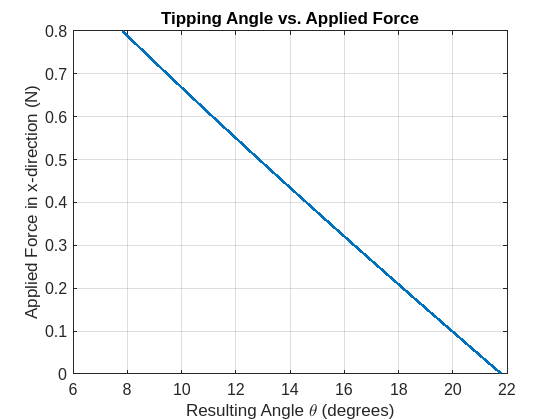

function F_fn = get_evaluator_fn(mass)
    syms F_x F_y F_z theta 'real'
    
    % Constants
    g       = 9.81;                 % Gravity; constant
    z_hat   = [0;       0;  1];     % Z-axis unit in box frame; constant

    
    % Experimental values
    e_hat   = [0;       1;  0];     % Tipped unit axis

   21.7831



    rf0     = [-0.08;   0;  0.15];  % Finger pos in box frame at t=0

Symbolic variables have been created.



--- General Equation for tan(theta) ---


             ez (Fx rfy0 - Fy rfx0) - ey (Fx rfz0 - Fz rfx0) + ex (Fy rfz0 - Fz rfy0) - g m (ez (rcy0 zx - rcx0 zy) - ey (rcz0 zx - rcx0 zz) + ex (rcz0 zy - rcy0 zz))
- -------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  Fx rfx0 + Fy rfy0 + Fz rfz0 - (ex rfx0 + ey rfy0 + ez rfz0) (Fx ex + Fy ey + Fz ez) - g m (rcx0 zx + rcy0 zy + rcz0 zz - (ex rcx0 + ey rcy0 + ez rcz0) (ex zx + ey zy + ez zz))




--- Now, substituting F = [0; 0; 0] ---


--- Simplified Result for tan(theta) when F = 0 ---


        ez (rcy0 zx - rcx0 zy) - ey (rcz0 zx - rcx0 zz) + ex (rcz0 zy - rcy0 zz)
- -----------------------------------------------------------------------------------
  rcx0 zx + rcy0 zy + rcz0 zz - (ex rcx0 + ey rcy0 + ez rcz0) (ex zx + ey zy + ez zz)



    rc0     = [-0.04;   0;  0.1];   % CoM pos in box frame at t=0

    F       = [F_x;     F_y;    F_z];

    % --- Symbolic equation setup ---
    % R_sym = axisangle2rot(e_hat, theta_sym);
    R = @(ang) axisangle2rot(e_hat, ang);
    
    A = R(theta) * cross(e_hat, rf0);
    B = mass*g * (rc0.' * (R(-theta) * cross(z_hat, e_hat)));

    % eq_full = F == (B/(A.'*A)) * A;           % min-norm force that satisfies A^T F = B
    eq_full = F == (B * inv(A.'*A)) * A;
    
    % --- F is already explicitly solved, just extract expressions from RHS
    expr = rhs(eq_full);
    
    % Create numeric function handle
    F_fn = matlabFunction(expr, 'Vars', {theta});
end


function r = axisangle2rot(axis, angle)
    % if abs(angle) > 10
    %     disp("Ensure angle is in radians");
    % end

    n = norm(axis);
    if n < eps, error('Axis vector must be nonzero.'); end

    e = axis / n; % Ensure unit axis
    e_skew = [  0, -e(3),  e(2);
             e(3),     0, -e(1);
            -e(2),  e(1),     0];

    c = cos(angle);
    s = sin(angle);

    % For symbolic or scalar angle, return single 3x3
    if isa(angle, 'sym') || isscalar(angle)
        R = eye(3)*c + (1-c)*(e*e.') + s*e_skew;
        r = R;
        return
    end

    % Rodrigues' formula
    E = e*e.'; % Outer product
    I3 = eye(3);

    R = zeros(3,3,numel(angle));
    for k =1:numel(angle)
        ck = c(k); sk = s(k);
        R(:,:,k) = I3*ck + (1-ck)*E + sk*e_skew;
    end
    r = R;
end